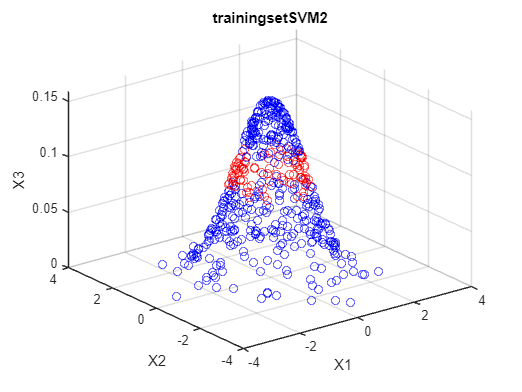

% 3.3

clc
clear

dataset = load('trainingsetSVM2.mat');

X = dataset.X;
Y = dataset.Y;

plot_dataset(X, Y, "trainingsetSVM2")

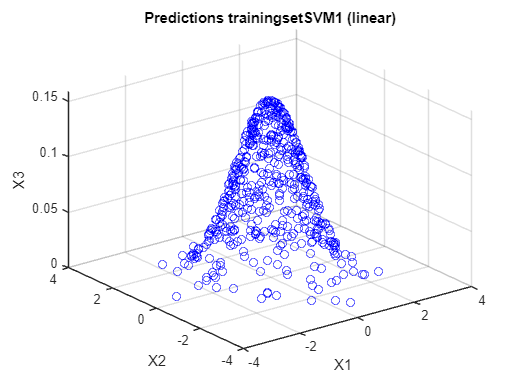


% Modelo con kernel lineal
linear_mdl = fitcsvm(X, Y, 'KernelFunction','linear', 'Standardize', true);
ye = predict(linear_mdl,X);

plot_dataset(X, ye, "Predictions trainingsetSVM1 (linear)");


error_rate = loss(linear_mdl, X, Y);
num_errors = error_rate * numel(Y);

fprintf('Número de errores: %d. Tasa de error: %.3f.\n\n', num_errors, error_rate);

Número de errores: 89. Tasa de error: 0.178.




% 3.4

n = 1;
max_iterations = 10;
error_rate = 1;
while (num_errors > 0)
    % Modelo con kernel polinomial de grado n
    pol_mdl = fitcsvm(X, Y, 'KernelFunction','polynomial', 'PolynomialOrder', n, 'Standardize', true);
    ye = predict(pol_mdl,X);
    error_rate = loss(pol_mdl, X, Y);
    num_errors = error_rate * numel(Y);
    fprintf('Grado del polinomio: %d. Número de errores: %.0f. Tasa de error: %.4f.\n', n, num_errors, error_rate);
    n = n+1;
end

Grado del polinomio: 1. Número de errores: 89. Tasa de error: 0.1780.
Grado del polinomio: 2. Número de errores: 14. Tasa de error: 0.0280.
Grado del polinomio: 3. Número de errores: 11. Tasa de error: 0.0220.
Grado del polinomio: 4. Número de errores: 1. Tasa de error: 0.0020.
Grado del polinomio: 5. Número de errores: 1. Tasa de error: 0.0020.
Grado del polinomio: 6. Número de errores: 2. Tasa de error: 0.0040.
Grado del polinomio: 7. Número de errores: 0. Tasa de error: 0.0000.


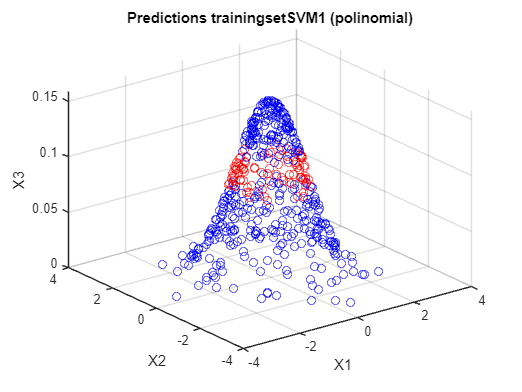

    plot_dataset(X, ye, "Predictions trainingsetSVM1 (polinomial)");

function plot_dataset(X, Y, plot_title)
    % Matrix containing the colors of every sample
    colors = zeros(size(Y, 1), 3);
    
    % If for sample n, Y(n) is -1, colors(n) will be [0, 0, 1]. Color blue
    % If for sample n, Y(n) is 1, colors(n) will be [1, 0, 0]. Color blue
    colors_class1 = repmat([0, 0, 1], sum(Y == -1), 1);
    colors_class2 = repmat([1, 0, 0], sum(Y == 1), 1);
    
    % Change original color value [0,0,0] to the new calculated value. R or B.
    colors(Y == -1, :) = colors_class1;
    colors(Y == 1, :) = colors_class2;
    
    % Plot the dataset with the new colors.
    scatter3(X(:,1), X(:,2), X(:,3), [], colors)
    xlabel('X1');
    ylabel('X2');
    zlabel('X3');
    title(plot_title);
end
